# Compile Figures for Synthetic Data

%%%%%%
%Script for compiling the figure generator
%%%%%%

clear all
close all


%What is your project name?
ProjFolder = 'CB_thawingdepth_disturbed_DOC/';

%do you want the figure saved?
printfig  = true;

%Where do you want to save files?
workdirfig_DOC = '/Users/cansu/Documents/GitHub/Permafrost_ERRA/datERRA/CB_thawingdepth_disturbed_DOC/figures/DOC';
workdirfig_POC = '/Users/cansu/Documents/GitHub/Permafrost_ERRA/datERRA/CB_thawingdepth_disturbed_DOC/figures/POC';
workdirfig_SSC = '/Users/cansu/Documents/GitHub/Permafrost_ERRA/datERRA/CB_thawingdepth_disturbed_DOC/figures/SSC';
workdirfig_TDS = '/Users/cansu/Documents/GitHub/Permafrost_ERRA/datERRA/CB_thawingdepth_disturbed_DOC/figures/TDS';

workdirfig_qDOC = '/Users/cansu/Documents/GitHub/Permafrost_ERRA/datERRA/CB_thawingdepth_disturbed_DOC/figures/qDOC';
workdirfig_qPOC = '/Users/cansu/Documents/GitHub/Permafrost_ERRA/datERRA/CB_thawingdepth_disturbed_DOC/figures/qPOC';
workdirfig_qSSC = '/Users/cansu/Documents/GitHub/Permafrost_ERRA/datERRA/CB_thawingdepth_disturbed_DOC/figures/qSSC';
workdirfig_qTDS = '/Users/cansu/Documents/GitHub/Permafrost_ERRA/datERRA/CB_thawingdepth_disturbed_DOC/figures/qTDS';


%Where is your data?
workdir = '/Users/cansu/Documents/GitHub/Permafrost_ERRA/datERRA/CB_thawingdepth_disturbed_DOC/';



Lets plot the results

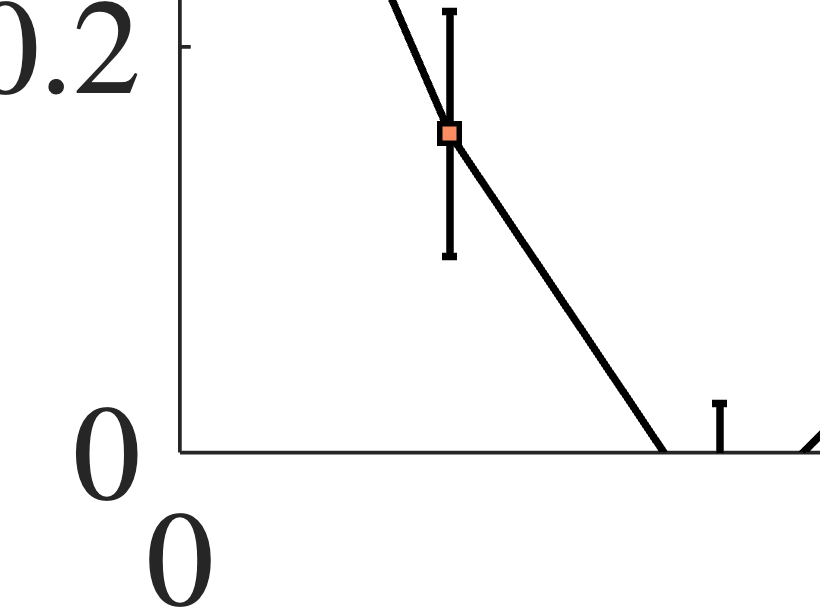

f4 =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [0.7000 12 9.3500 7]
       Units: 'inches'

  Show all properties


% % %Plot time with discharge and precipitation. This function will change
% % %depending on data format. Please change this function accordingly
% % origdat=char(strcat(originaldata(1)));
% % f1 = figtQP_plot_UK(origdat,workdir,workdirfig,printfig)

cd(workdir)
%Plot lagtime with RRD
str = {'Rresults/1hr_simple_DOC_RRD.txt'};
f4 = figtRRD_plot_dZ({'Ptarmigan, Disturbed by Active', 'Layer Detachment Slides (ALDSs)'},workdir,workdirfig_DOC,printfig,1,str,'DOC-RRD [mg/(mm$\cdot$L$\cdot$day)]',4)

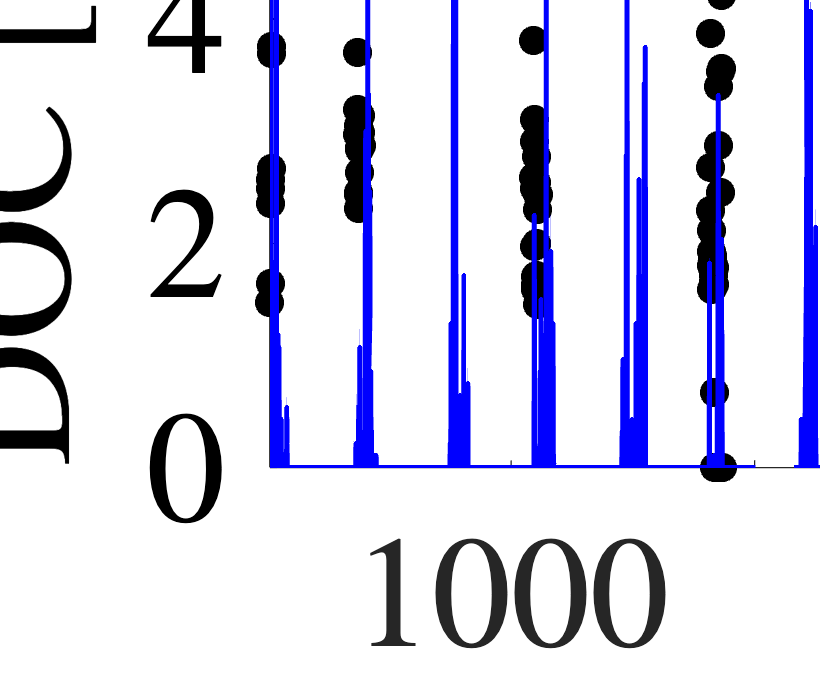

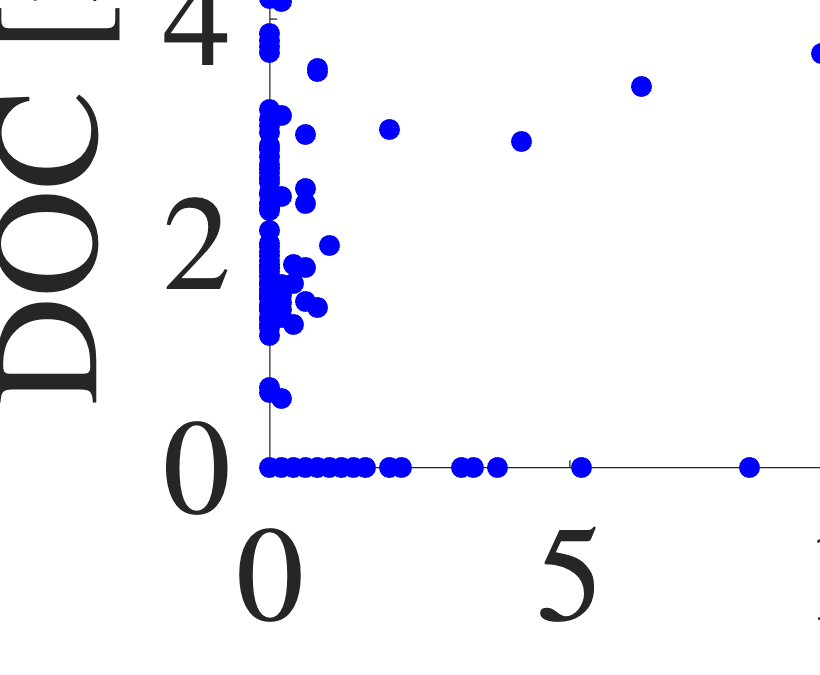

f5 =   Figure (5) with properties:

      Number: 5
        Name: ''
       Color: [1 1 1]
    Position: [0.7000 12 8.1500 6.7000]
       Units: 'inches'

  Show all properties


str = {'Rresults/1hr_simple_DOC_Qcomp.txt'};
f5 = figDOC_P_plot_CB('DOC [mg/L]',workdir,workdirfig_DOC,printfig,str)

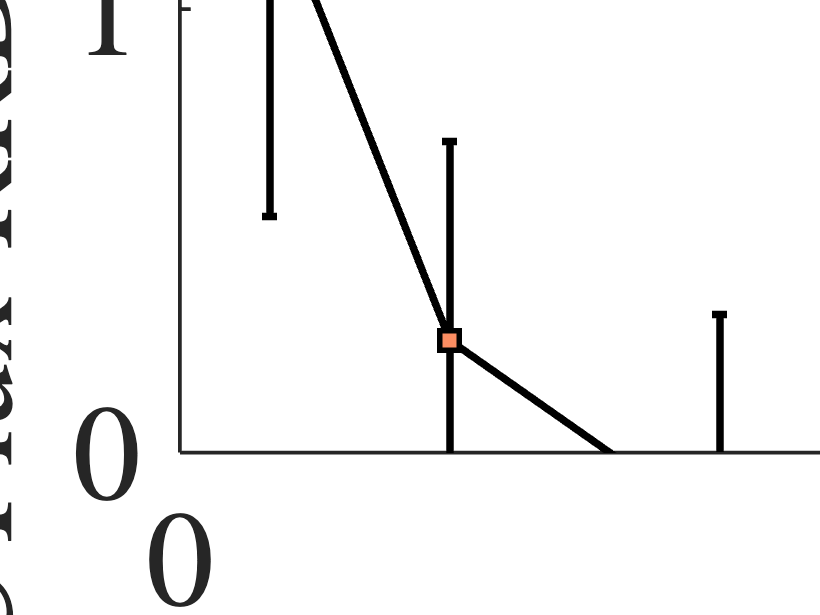

f4 =   Figure (6) with properties:

      Number: 6
        Name: ''
       Color: [1 1 1]
    Position: [0.7000 12 9.3500 7]
       Units: 'inches'

  Show all properties




str = {'Rresults_flux/1hr_simple_DOC_RRD.txt'};
f4 = figtRRD_plot_dZ('',workdir,workdirfig_qDOC,printfig,1,str,'DOC Flux-RRD [mg/(L$\cdot$ day)]',4) %'Ptarmigan, Melville Island (NU) Disturbed; DOC Flux'

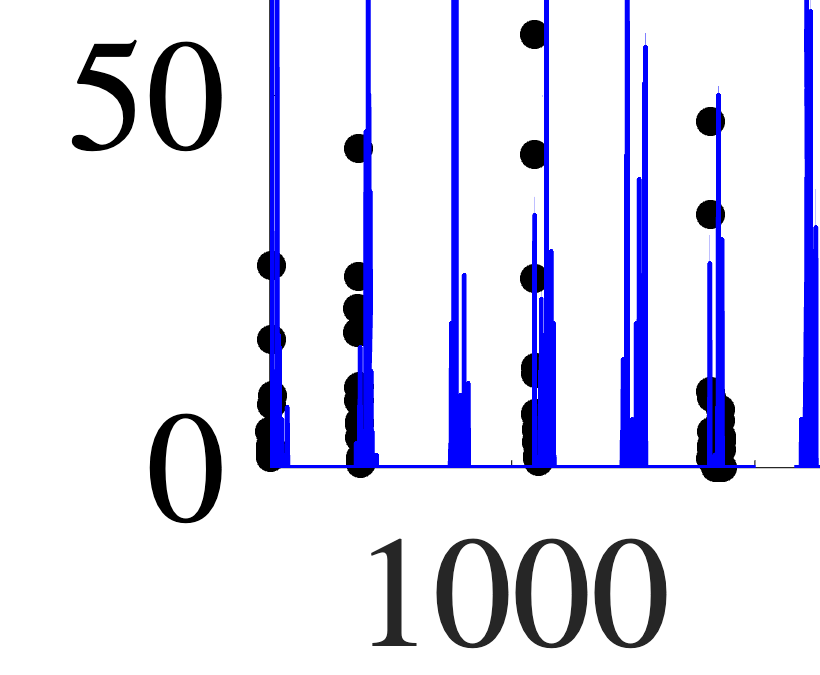

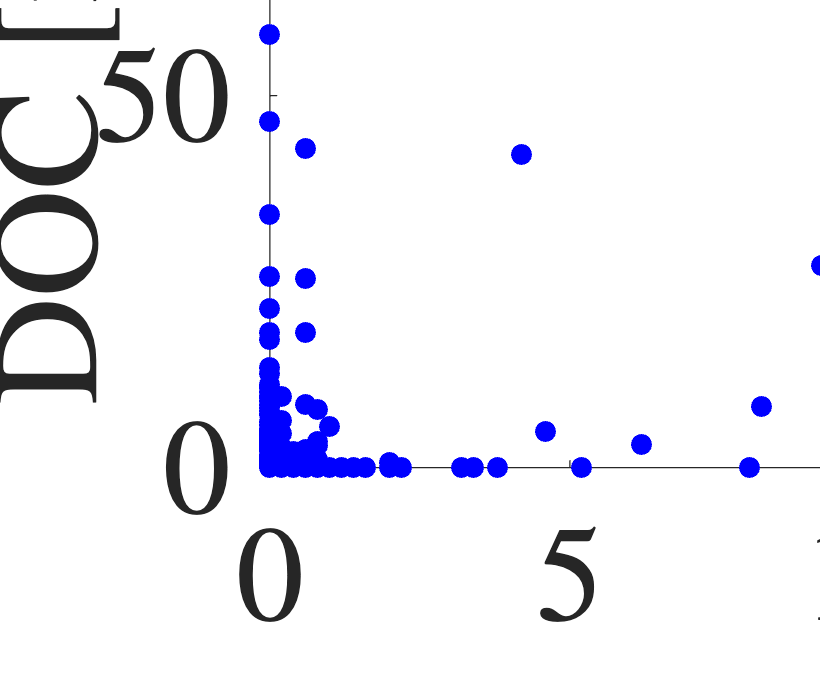

f5 =   Figure (8) with properties:

      Number: 8
        Name: ''
       Color: [1 1 1]
    Position: [0.7000 12 8.1500 6.7000]
       Units: 'inches'

  Show all properties


str = {'Rresults_flux/1hr_simple_DOC_Qcomp.txt'};
f5 = figDOC_P_plot_CB('DOC Flux [mg$\cdot$mm/(L$\cdot$ day)]',workdir,workdirfig_qDOC,printfig,str)


cd(workdir)
%Plot lagtime with RRD
str = {'Rresults/1hr_simple_POC_RRD.txt'};
f4 = figtRRD_plot_dZ('Ptarmigan, Melville Island (NU) Disturbed; POC',workdir,workdirfig_POC,printfig,1,str,'POC',4)
str = {'Rresults_flux/1hr_simple_POC_RRD.txt'};
f4 = figtRRD_plot_dZ('Ptarmigan, Melville Island (NU) Disturbed; POC Flux',workdir,workdirfig_qPOC,printfig,1,str,'POC Flux',4)

% 


cd(workdir)
%Plot lagtime with RRD
str = {'Rresults/1hr_simple_SSC_RRD.txt'};
f4 = figtRRD_plot_dZ('Ptarmigan, Melville Island (NU) Disturbed; SSC',workdir,workdirfig_SSC,printfig,1,str,'SSC',4)



cd(workdir)
%Plot lagtime with RRD
str = {'Rresults/1hr_simple_TDS_RRD.txt'};
f4 = figtRRD_plot_dZ('Ptarmigan, Melville Island (NU) Disturbed; TDS',workdir,workdirfig_TDS,printfig,1,str,'TDS',4)

str = {'Rresults_flux/1hr_simple_TDS_RRD.txt'};
f4 = figtRRD_plot_dZ('Ptarmigan, Melville Island (NU) Disturbed; TDS Flux',workdir,workdirfig_qTDS,printfig,1,str,'TDS Flux',4)

